# fox rabbit chase

## Question 1: Constant speeds

sr = 13;
sf = 16; % speeds of rabbit/fox
z0 = [250, -550]; % initial position of the fox
burrow = [600, 600]; % position of the burrow
ts = [0 norm(burrow)/sr]; % time span
mindist = 0.1;
options = odeset('RelTol',1e-8,'AbsTol',1e-10, ...
    'Events',@(t,z)foxrab1(t,z,sr,mindist,burrow));
[t,z,te,ze,zi]=ode45(@(t,z)foxode1(t,z,sr,sf),ts,z0,options);
te,ze,zi

te = 65.2637

ze =   450.3016  413.8831


zi = 2

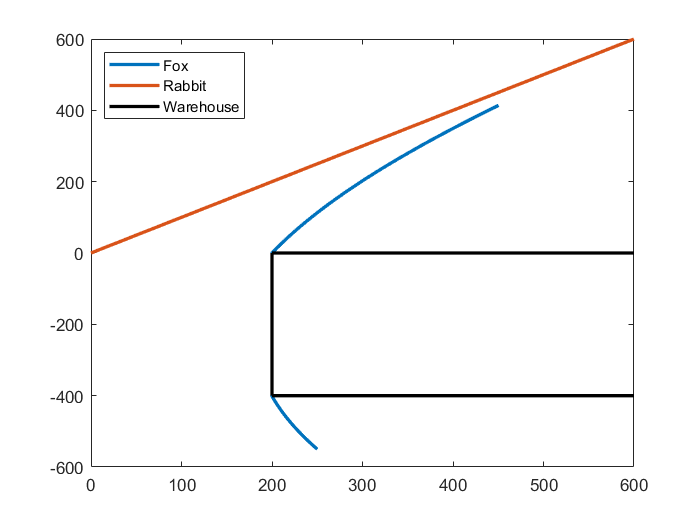

plot(z(:,1),z(:,2),sqrt(2)/2*sr*t,sqrt(2)/2*sr*t, ...
    [200,600],[0,0],'k',[200,600],[-400,-400],'k', ...
    [200,200],[-400,0],'k','Linewidth',2)
lg = legend('Fox','Rabbit','Warehouse','Location','northwest');

## Question 2: Diminishing speeds

sr0 = 13;
sf0 = 16; % initial speeds of rabbit/fox
z0 = [250, -550]; % initial position of the fox
burrow = [600, 600]; % position of the burrow
ts = [0, (norm(burrow)/sr0 + ...
    norm(burrow)/(sr0*exp(-0.0008*norm(burrow))))/2];
mindist = 0.1;
options = odeset('RelTol',1e-8,'AbsTol',1e-10, ...
    'Events',@(t,z)foxrab2(t,z,sr0,mindist,burrow));
[t,z,te,ze,zi]=ode45(@(t,z)foxode2(t,z,sr0,sf0),ts,z0,options);
te,ze,zi

te = 67.2793

ze =   307.1431  307.1311


zi = 1

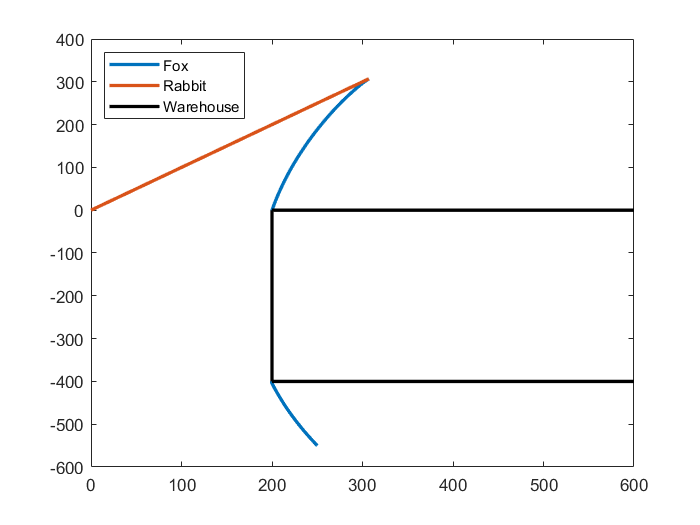

plot(z(:,1),z(:,2),[0:ze(1)],[0:ze(2)], ...
    [200,600],[0,0],'k',[200,600],[-400,-400],'k', ...
    [200,200],[-400,0],'k','Linewidth',2)
lg = legend('Fox','Rabbit','Warehouse','Location','northwest');